clear all
figure

data = readtable("Optimisation7.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2 
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______<


resultTab = data{:, :};
resultTab = resultTab(:,[11,12,13])

resultTab =     0.4619   -2.3979    1.6216
   -0.1830   -2.3979    2.5904
    0.0546   -2.3979    1.7886
    1.2713   -2.3026    1.1980
    0.0055   -2.3979    2.3444
   -0.3183   -2.3979    2.6093
    1.2074   -2.3979    1.1613
   -0.4452   -2.3979    2.1572
   -0.4966   -2.3979    1.8920
    0.0280   -2.3979    1.6566



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.6301   -2.3979    1.6216
    1.2008   -2.3979    2.5904
    0.9468   -2.3979    1.7886
    0.2805   -2.3026    1.1980
    0.9946   -2.3979    2.3444
    1.3749   -2.3979    2.6093
    0.2990   -2.3979    1.1613
    1.5608   -2.3979    2.1572
    1.6431   -2.3979    1.8920
    0.9724   -2.3979    1.6566


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.6301   11.0000    1.6216
    1.2008   11.0000    2.5904
    0.9468   11.0000    1.7886
    0.2805   10.0000    1.1980
    0.9946   11.0000    2.3444
    1.3749   11.0000    2.6093
    0.2990   11.0000    1.1613
    1.5608   11.0000    2.1572
    1.6431   11.0000    1.8920
    0.9724   11.0000    1.6566


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.6301   11.0000   -5.0611
    1.2008   11.0000  -13.3357
    0.9468   11.0000   -5.9808
    0.2805   10.0000   -3.3135
    0.9946   11.0000  -10.4272
    1.3749   11.0000  -13.5894
    0.2990   11.0000   -3.1941
    1.5608   11.0000   -8.6472
    1.6431   11.0000   -6.6327
    0.9724   11.0000   -5.2417



utopiaPoint1 = [max(resultTab(:,1)), max(resultTab(:,2)), max(resultTab(:,3))]

utopiaPoint1 =     1.6555   11.0000   -2.1769


antiutopiaPointTemp = [min(resultTab(:,1)), min(resultTab(:,2)), min(resultTab(:,3))]

antiutopiaPointTemp =     0.2768    9.0000  -14.5601



antiutopiaPointCorr = 0.01.*(utopiaPoint1-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0138    0.0200    0.1238


antiutopiaPoint1 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint1 =     0.2630    8.9800  -14.6839



data = readtable("Optimisation8.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph    RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018    Dist2
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    ________    __________________    __________________    _________________    ______________________    _____


resultTab = data{:, :};
resultTab = resultTab(:,[11,12,13])

resultTab =     0.0266   -2.3026    2.1527
    0.0313   -2.3979    2.2657
    0.2581   -2.3979    1.6592
   -0.2265   -2.3979    2.1533
    0.5864   -2.3979    1.5498
   -0.1757   -2.1972    2.6599
    0.6036   -2.3979    2.0025
    0.3001   -2.3026    1.9519
    0.4513   -2.3979    1.5138
   -0.2924   -2.3979    2.0343



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.9737   -2.3026    2.1527
    0.9692   -2.3979    2.2657
    0.7725   -2.3979    1.6592
    1.2542   -2.3979    2.1533
    0.5563   -2.3979    1.5498
    1.1921   -2.1972    2.6599
    0.5468   -2.3979    2.0025
    0.7408   -2.3026    1.9519
    0.6368   -2.3979    1.5138
    1.3397   -2.3979    2.0343


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.9737   10.0000    2.1527
    0.9692   11.0000    2.2657
    0.7725   11.0000    1.6592
    1.2542   11.0000    2.1533
    0.5563   11.0000    1.5498
    1.1921    9.0000    2.6599
    0.5468   11.0000    2.0025
    0.7408   10.0000    1.9519
    0.6368   11.0000    1.5138
    1.3397   11.0000    2.0343


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.9737   10.0000   -8.6083
    0.9692   11.0000   -9.6379
    0.7725   11.0000   -5.2552
    1.2542   11.0000   -8.6130
    0.5563   11.0000   -4.7104
    1.1921    9.0000  -14.2951
    0.5468   11.0000   -7.4073
    0.7408   10.0000   -7.0423
    0.6368   11.0000   -4.5437
    1.3397   11.0000   -7.6472



utopiaPoint2 = [max(resultTab(:,1)), max(resultTab(:,2)), max(resultTab(:,3))]

utopiaPoint2 =     1.4831   11.0000   -2.1565


antiutopiaPointTemp = [min(resultTab(:,1)), min(resultTab(:,2)), min(resultTab(:,3))]

antiutopiaPointTemp =     0.1660    9.0000  -14.2951



antiutopiaPointCorr = 0.01.*(utopiaPoint2-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0132    0.0200    0.1214


antiutopiaPoint2 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint2 =     0.1528    8.9800  -14.4165



data = readtable("Optimisation9.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2 
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______<


resultTab = data{:, :};
resultTab = resultTab(:,[11,12,13])

resultTab =     0.6015   -2.3979    1.5096
    1.0731   -2.3979    2.0303
   -0.0503   -2.3979    1.6280
   -0.3661   -2.3979    1.7432
    0.3320   -2.3026    2.0901
   -0.1753   -2.3979    2.6105
    0.1729   -2.3026    2.1625
   -0.3716   -2.3979    2.3225
   -0.3910   -2.3979    2.0774
   -0.4569   -2.3979    1.8207



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.5480   -2.3979    1.5096
    0.3419   -2.3979    2.0303
    1.0516   -2.3979    1.6280
    1.4421   -2.3979    1.7432
    0.7175   -2.3026    2.0901
    1.1916   -2.3979    2.6105
    0.8413   -2.3026    2.1625
    1.4501   -2.3979    2.3225
    1.4784   -2.3979    2.0774
    1.5792   -2.3979    1.8207


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.5480   11.0000    1.5096
    0.3419   11.0000    2.0303
    1.0516   11.0000    1.6280
    1.4421   11.0000    1.7432
    0.7175   10.0000    2.0901
    1.1916   11.0000    2.6105
    0.8413   10.0000    2.1625
    1.4501   11.0000    2.3225
    1.4784   11.0000    2.0774
    1.5792   11.0000    1.8207


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.5480   11.0000   -4.5249
    0.3419   11.0000   -7.6164
    1.0516   11.0000   -5.0939
    1.4421   11.0000   -5.7157
    0.7175   10.0000   -8.0857
    1.1916   11.0000  -13.6064
    0.8413   10.0000   -8.6928
    1.4501   11.0000  -10.2008
    1.4784   11.0000   -7.9837
    1.5792   11.0000   -6.1760



utopiaPoint3 = [max(resultTab(:,1)), max(resultTab(:,2)), max(resultTab(:,3))]

utopiaPoint3 =     1.5792   11.0000   -2.3674


antiutopiaPointTemp = [min(resultTab(:,1)), min(resultTab(:,2)), min(resultTab(:,3))]

antiutopiaPointTemp =     0.1214    9.0000  -13.6064



antiutopiaPointCorr = 0.01.*(utopiaPoint3-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0146    0.0200    0.1124


antiutopiaPoint3 = antiutopiaPointTemp - antiutopiaPointCorr

antiutopiaPoint3 =     0.1068    8.9800  -13.7187




utopiaPoint = max([utopiaPoint1; utopiaPoint2; utopiaPoint3])

utopiaPoint =     1.6555   11.0000   -2.1565


antiutopiaPoint = min([antiutopiaPoint1;antiutopiaPoint2;antiutopiaPoint3])

antiutopiaPoint =     0.1068    8.9800  -14.6839


%Optimisation 7
figure

load("Optimisation7.mat")

dataTab = data{2, 2};
dataTab = dataTab{:,[1,2,5]}

dataTab =     9.7600   51.8900    3.1300
    5.4300   37.9900    9.9700
    4.1000   13.2800    1.6400
    6.1900   57.9400    5.2200
    3.1400    8.4600    6.6600
    8.1800   28.0300    7.9000
    1.8000   34.4000    0.6400
    9.3072   18.8005    1.6755
    9.5944   28.8408    0.2934
    7.2340   43.5292    1.2045



resultTab = data{3, 2};
resultTab = resultTab{:,[1,2,3]};
resultTab = cell2mat(resultTab)

resultTab =     0.4619   -2.3979    1.6216
   -0.1830   -2.3979    2.5904
    0.0546   -2.3979    1.7886
    1.2713   -2.3026    1.1980
    0.0055   -2.3979    2.3444
   -0.3183   -2.3979    2.6093
    1.2074   -2.3979    1.1613
   -0.4452   -2.3979    2.1572
   -0.4966   -2.3979    1.8920
    0.0280   -2.3979    1.6566



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.6301   -2.3979    1.6216
    1.2008   -2.3979    2.5904
    0.9468   -2.3979    1.7886
    0.2805   -2.3026    1.1980
    0.9946   -2.3979    2.3444
    1.3749   -2.3979    2.6093
    0.2990   -2.3979    1.1613
    1.5608   -2.3979    2.1572
    1.6431   -2.3979    1.8920
    0.9724   -2.3979    1.6566


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.6301   11.0000    1.6216
    1.2008   11.0000    2.5904
    0.9468   11.0000    1.7886
    0.2805   10.0000    1.1980
    0.9946   11.0000    2.3444
    1.3749   11.0000    2.6093
    0.2990   11.0000    1.1613
    1.5608   11.0000    2.1572
    1.6431   11.0000    1.8920
    0.9724   11.0000    1.6566


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.6301   11.0000   -5.0611
    1.2008   11.0000  -13.3357
    0.9468   11.0000   -5.9808
    0.2805   10.0000   -3.3135
    0.9946   11.0000  -10.4272
    1.3749   11.0000  -13.5894
    0.2990   11.0000   -3.1941
    1.5608   11.0000   -8.6472
    1.6431   11.0000   -6.6327
    0.9724   11.0000   -5.2417



paretoF = paretoFront([resultTab(:,1) resultTab(:,2) resultTab(:,3)])

paretoF =     0.5444   11.0000   -3.0083
    1.0076   11.0000   -3.7863
    1.3994   11.0000   -4.8479
    1.6555   11.0000   -5.5672
    0.7478   10.0000   -2.4654
    0.2768   10.0000   -2.1769
    1.5849   11.0000   -5.1806
    0.7392   11.0000   -3.5598
    0.9732   11.0000   -3.6535
    1.6160   11.0000   -5.3655


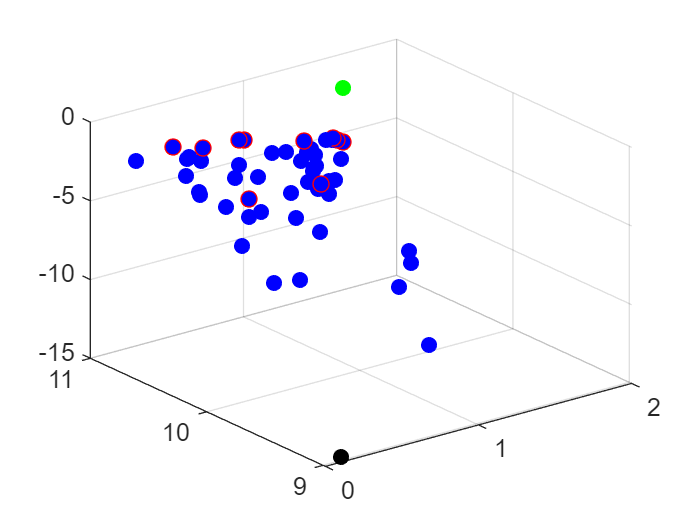


scatter3(resultTab(:,1), resultTab(:,2), resultTab(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off


allHV = [];
for x = 7:length(resultTab(:,1))

    paretoF = paretoFront([resultTab(1:x,1) resultTab(1:x,2) resultTab(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.4559
   -0.6109
   -0.7088
   -0.7237
   -0.7237
   -0.7237
   -0.7437
   -0.7437
   -0.7437
   -0.7567


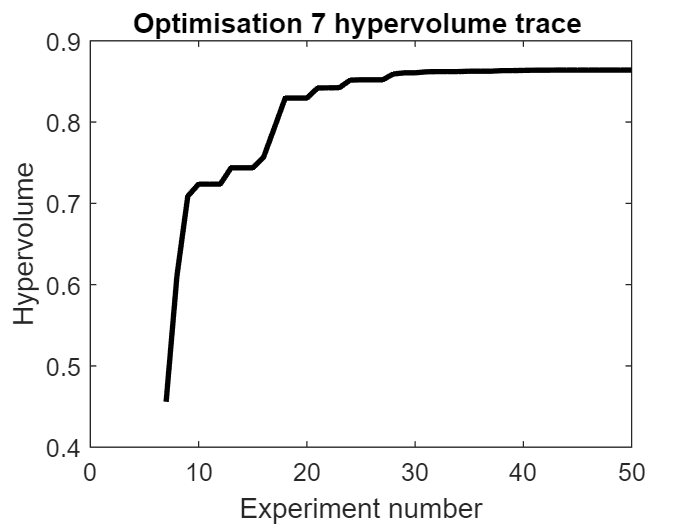


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 7 hypervolume trace ")

%Optimisation 8
figure

load("Optimisation8.mat")

dataTab = data{2, 2};
dataTab = dataTab{:,[1,2,5]}

dataTab =     2.7600   34.7900    5.6500
    5.7700   42.9500    6.9200
    6.4900   47.6200    2.1300
    9.7200   14.1000    1.1600
    1.5200   53.6800    9.1600
    7.9800   21.4700    8.1800
    4.2800    7.3500    2.8600
    4.3115   48.2502    9.8666
   10.0000   51.8155    1.5105
    8.9225   28.5459    1.5654



resultTab = data{3, 2};
resultTab = resultTab{:,[1,2,3]};
resultTab = cell2mat(resultTab)

resultTab =     0.0266   -2.3026    2.1527
    0.0313   -2.3979    2.2657
    0.2581   -2.3979    1.6592
   -0.2265   -2.3979    2.1533
    0.5864   -2.3979    1.5498
   -0.1757   -2.1972    2.6599
    0.6036   -2.3979    2.0025
    0.3001   -2.3026    1.9519
    0.4513   -2.3979    1.5138
   -0.2924   -2.3979    2.0343



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.9737   -2.3026    2.1527
    0.9692   -2.3979    2.2657
    0.7725   -2.3979    1.6592
    1.2542   -2.3979    2.1533
    0.5563   -2.3979    1.5498
    1.1921   -2.1972    2.6599
    0.5468   -2.3979    2.0025
    0.7408   -2.3026    1.9519
    0.6368   -2.3979    1.5138
    1.3397   -2.3979    2.0343


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.9737   10.0000    2.1527
    0.9692   11.0000    2.2657
    0.7725   11.0000    1.6592
    1.2542   11.0000    2.1533
    0.5563   11.0000    1.5498
    1.1921    9.0000    2.6599
    0.5468   11.0000    2.0025
    0.7408   10.0000    1.9519
    0.6368   11.0000    1.5138
    1.3397   11.0000    2.0343


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.9737   10.0000   -8.6083
    0.9692   11.0000   -9.6379
    0.7725   11.0000   -5.2552
    1.2542   11.0000   -8.6130
    0.5563   11.0000   -4.7104
    1.1921    9.0000  -14.2951
    0.5468   11.0000   -7.4073
    0.7408   10.0000   -7.0423
    0.6368   11.0000   -4.5437
    1.3397   11.0000   -7.6472



paretoF = paretoFront([resultTab(:,1) resultTab(:,2) resultTab(:,3)])

paretoF =     0.3013   11.0000   -2.9262
    1.3131   11.0000   -5.2221
    1.1686    9.0000   -2.9595
    0.6652   11.0000   -3.4579
    0.7985   11.0000   -3.5610
    0.7794    9.0000   -2.1565
    1.0497    9.0000   -2.2104
    0.8485   10.0000   -2.4871
    0.9151   11.0000   -3.9975
    0.9850   11.0000   -4.4760


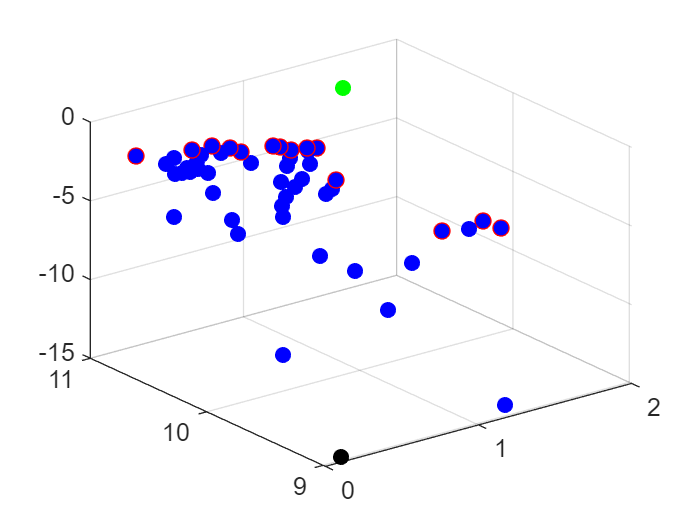

hv = 0.7720


scatter3(resultTab(:,1), resultTab(:,2), resultTab(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab(:,1))

    paretoF = paretoFront([resultTab(1:x,1) resultTab(1:x,2) resultTab(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.4877
   -0.4877
   -0.4939
   -0.5478
   -0.5495
   -0.5774
   -0.5782
   -0.6129
   -0.6218
   -0.6237


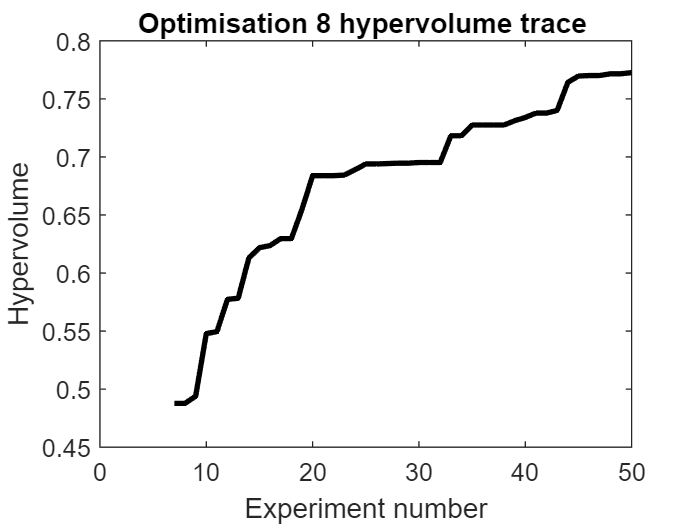


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 8 hypervolume trace ")

%Optimisation 9
figure

load("Optimisation9.mat")

dataTab = data{2, 2};
dataTab = dataTab{:,[1,2,5]}

dataTab =     9.9400   53.9400    6.2000
    4.5400    6.4500    2.8800
    2.6700   29.7500    1.9600
    6.9500   25.4000    0.2400
    1.4500   19.0700    5.6400
    8.6800   39.1400    9.9300
    5.6400   46.0400    7.5300
   10.0000   19.8613    3.0027
    9.1517   22.8791    1.3703
    9.7763   32.6525    0.1465



resultTab = data{3, 2};
resultTab = resultTab{:,[1,2,3]};
resultTab = cell2mat(resultTab)

resultTab =     0.6015   -2.3979    1.5096
    1.0731   -2.3979    2.0303
   -0.0503   -2.3979    1.6280
   -0.3661   -2.3979    1.7432
    0.3320   -2.3026    2.0901
   -0.1753   -2.3979    2.6105
    0.1729   -2.3026    2.1625
   -0.3716   -2.3979    2.3225
   -0.3910   -2.3979    2.0774
   -0.4569   -2.3979    1.8207



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.5480   -2.3979    1.5096
    0.3419   -2.3979    2.0303
    1.0516   -2.3979    1.6280
    1.4421   -2.3979    1.7432
    0.7175   -2.3026    2.0901
    1.1916   -2.3979    2.6105
    0.8413   -2.3026    2.1625
    1.4501   -2.3979    2.3225
    1.4784   -2.3979    2.0774
    1.5792   -2.3979    1.8207


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.5480   11.0000    1.5096
    0.3419   11.0000    2.0303
    1.0516   11.0000    1.6280
    1.4421   11.0000    1.7432
    0.7175   10.0000    2.0901
    1.1916   11.0000    2.6105
    0.8413   10.0000    2.1625
    1.4501   11.0000    2.3225
    1.4784   11.0000    2.0774
    1.5792   11.0000    1.8207


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.5480   11.0000   -4.5249
    0.3419   11.0000   -7.6164
    1.0516   11.0000   -5.0939
    1.4421   11.0000   -5.7157
    0.7175   10.0000   -8.0857
    1.1916   11.0000  -13.6064
    0.8413   10.0000   -8.6928
    1.4501   11.0000  -10.2008
    1.4784   11.0000   -7.9837
    1.5792   11.0000   -6.1760



paretoF = paretoFront([resultTab(:,1) resultTab(:,2) resultTab(:,3)])

paretoF =     1.0516   11.0000   -5.0939
    1.5792   11.0000   -6.1760
    0.9813   11.0000   -4.4782
    1.1565    9.0000   -2.9292
    0.7459   10.0000   -3.0867
    1.4854   11.0000   -5.5580
    0.4058   11.0000   -2.5742
    0.5910   10.0000   -2.3674
    0.5902   11.0000   -3.3285
    1.2762   11.0000   -5.1425


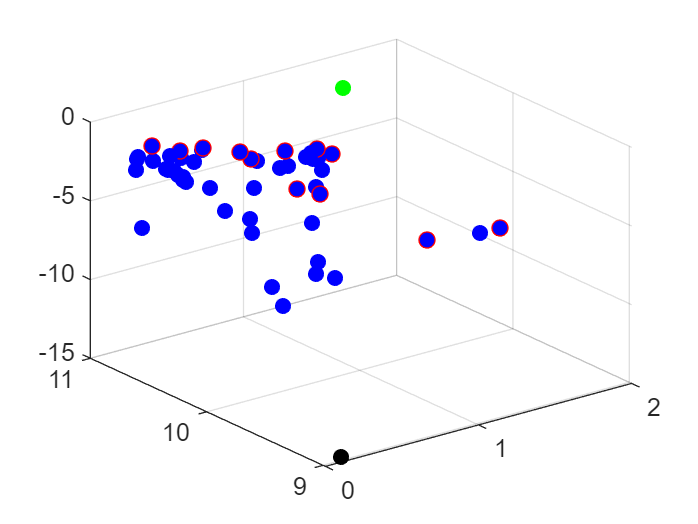

hv = 0.8008


scatter3(resultTab(:,1), resultTab(:,2), resultTab(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab(:,1))

    paretoF = paretoFront([resultTab(1:x,1) resultTab(1:x,2) resultTab(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.6604
   -0.6620
   -0.6729
   -0.7198
   -0.7353
   -0.7421
   -0.7432
   -0.7511
   -0.7520
   -0.7520


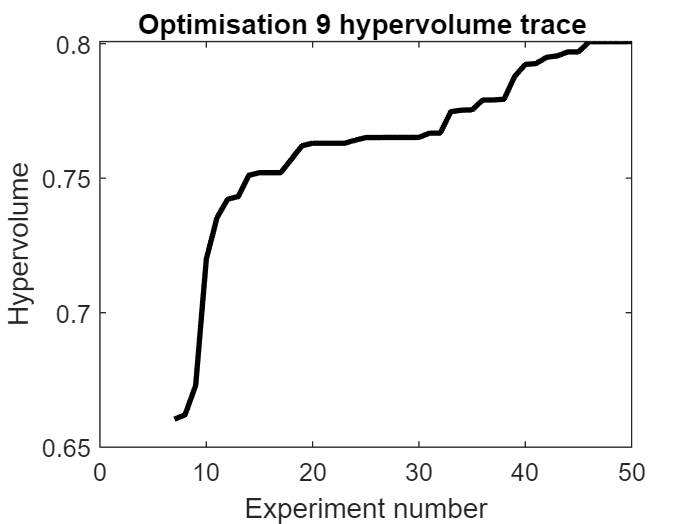


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 9 hypervolume trace ")